# ______________Computational Electromagnetics 

## _______________________________ Hw6-Q4

______________________Mohammadreza Arani         :::::::::::::         810100511

 __________________________________________1401/09/30   

clear; clc; close all;

a = 1/2;
W = 0.125:0.25:1.125;
d = 0.375;
eps0 = 8.854*1e-12  ;  % F/m

Sweep_N = [ 9 , 16 , 25 , 36 , 49 , 64  , 81 , 100];

C       = zeros( length(W) , length(Sweep_N));
C_plate = zeros( length(W),1);

A  = (2*a)^2;

Alpha_t =cell(1,length(W)) ;

for i=1:length(W)
    for j=1:length(Sweep_N)
        
        [C(i,j) , Alpha_t{i}] = Find_C(W(i) , Sweep_N(j),a ,d );

    end
    C_plate(i,1) =  2*(eps0*A/W(i) + eps0*A/d + eps0*A/ sqrt( W(i)^2 + d^2 )  ) ;

end


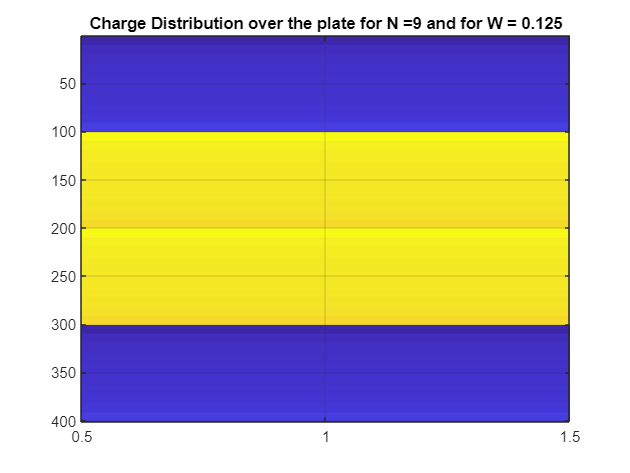



Charge_Distribution = Alpha_t{1};

figure(4)
imagesc(Charge_Distribution)
title("Charge Distribution over the plate for N =" + num2str(Sweep_N(1))+ " and for W = "+num2str(W(1)))
grid on

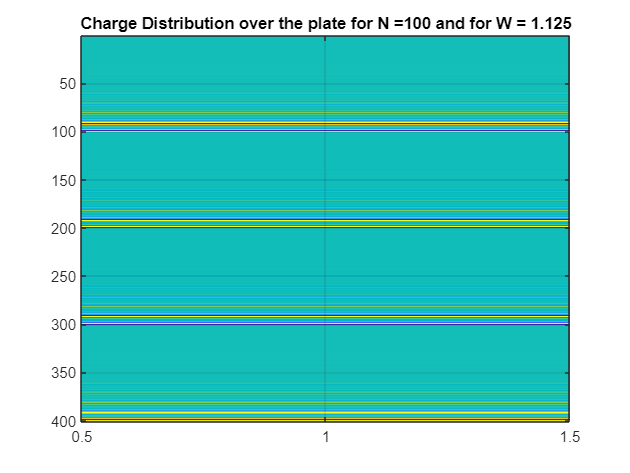




Charge_Distribution_end = Alpha_t{end};

figure(5)
imagesc(Charge_Distribution_end)
title("Charge Distribution over the plate for N =" + num2str(Sweep_N(end))+ " and for W = "+num2str(W(end)))
grid on

function   X_pos = Find_Cordx(m , N )

    if(m > sqrt(N) )
        Rem =  m - sqrt(N);
        X_pos = Find_Cordx(Rem , N);
    else
        X_pos  = ( m - 1/2);
    end
end

function   Y_pos = Find_Cordy(m , N )

     Y_pos =floor(m/sqrt(N+1)+1)*1 -  1/2;
end

function  R  = R_finder(m,n,delta_X,delta_Y,N, reside,W)
    if(reside ==0 )
        R =               abs(  delta_X*Find_Cordx(m , N ) - delta_X*Find_Cordx(n , N ) )^2  + ...
                          abs(  delta_Y*Find_Cordy(m , N ) - delta_Y*Find_Cordy(n , N ) )^2  ;
    else
        R =               abs(  delta_X*Find_Cordx(m , N ) - delta_X*Find_Cordx(n , N ) )^2  + ...
                          abs(  delta_Y*Find_Cordy(m , N ) - delta_Y*(W+Find_Cordy(n , N )) )^2  ;
    
    end
end

function lmn =  lmn_tt(m, n , delta_Sn , delta_X ,  delta_Y , N )
    eps0 = 8.854*1e-12  ;  % F/m

    if(m==n)
        lmn = (sqrt(delta_Sn)/eps0)*0.2806;
    else
        lmn =  delta_Sn/(4*pi*eps0*sqrt( R_finder(m,n,delta_X,delta_Y,N,0,0))  ) ;
    end
   
end



function lmn =  lmn_rl(m, n , delta_Sn , delta_X ,  delta_Y , N , W)
    eps0 = 8.854*1e-12  ;  % F/m
%     aeq  = sqrt(delta_Sn/pi)  ;
    reside =1;

    lmn =  delta_Sn/(4*pi*eps0*  sqrt( R_finder(m,n,delta_X,delta_Y,N, reside,W) ))  ;
   
end

function lmn =  lmn_tb(m, n , delta_Sn , delta_X ,  delta_Y , N , d)
    eps0 = 8.854*1e-12  ;  % F/m
    aeq  = sqrt(delta_Sn/pi)  ;

    if(m==n)
        lmn =  1/(2*eps0) * (sqrt(aeq^2+d^2) - d ) ;
    else
        lmn =  delta_Sn/(4*pi*eps0*  sqrt(R_finder(m,n,delta_X,delta_Y,N,0,0)+d^2)  ) ;
    end
   
end

function lmn = lmn_diag(m,n,delta_Sn , delta_X, delta_Y , N , W , d)


    eps0 = 8.854*1e-12  ;  % F/m
%     aeq  = sqrt(delta_Sn/pi)  ;
    reside =1;

    lmn =  delta_Sn/(4*pi*eps0*  sqrt( d^2 + R_finder(m,n,delta_X,delta_Y,N, reside,W) ))  ;

end


function [C , Alpha_t] = Find_C(W, N,a ,d)

    L11 = zeros(N,N);
    
    L13 = zeros(N,N);
    L14 = L13;
    L12 = L13;

    V =1;
    b = a / sqrt(N);
    delta_Sn  =  (2*b)^2 ;
    % eps0 = 8.854*1e-12  ;  % F/m
    delta_X = 2*b;
    delta_Y = 2*b;
    
    for i=1:N
        for j=1:N
            L11(i,j)  = lmn_tt(i, j , delta_Sn , delta_X ,  delta_Y , N );
            L13(i,j)  = lmn_rl(i, j , delta_Sn , delta_X ,  delta_Y , N , W);
            L14(i,j)  = lmn_diag(i,j,delta_Sn , delta_X, delta_Y , N , W , d);
            L12(i,j)  = lmn_tb(i, j , delta_Sn , delta_X ,  delta_Y , N , d);
        end
    end
    

    L = [L11 ,  L12 , L13 , L14 ; L12 , L11 , L14, L13 ; L13 , L14 , L11 , L12 ; L14 , L13 , L12 , L11 ];

    Alpha_t = inv( L ) * [V*ones(N,1) ; -V*ones(N,1); -V*ones(N,1); V*ones(N,1) ];
    
    C = 1/(V) * sum([Alpha_t(1:N,:) ; Alpha_t(end-N+1,end) ],'all')*delta_Sn;

end




